# PageRank - Utilizzo e test dell'algoritmo

Questo script file ha l'obiettivo di leggere un file contenente una matrice di adiacenze `G` e un cell array `U` di URL e utilizzare la funzione `PageRank` per calcolare il page rank. Lo script calcola:

- un grafico che visualizza la struttura di G e il grafo associato,

- i primi 15 risultati in ordine decrescente, con i corrispondenti outdegree e indegree,

- un grafico a barre del PageRank,

- il sottografo costituito dai nodi con rank maggiore della media dei rank.

Infine, sono presentati un test di correttezza dell'algoritmo implementato, confrontato con funzione `centrality` offerta da Matlab, e i test di robustezza implementati.

Innanzitutto, libero il workspace e carico la matrice G e il cell array U dal file `'repubblica.mat':`

clear
load repubblica.mat
% [U,G] = surfer('http://www.unina.it',100);

*NB: è possibile rieseguire lo script file, allegato alla documentazione, caricando una diversa matrice (e.g. *`mathwork200.mat`*) oppure utilizzando la funzione *`surfer`* come mostrato nel codice.*

## Struttura di G e grafo associato

Attraverso il comando `spy`, viene visualizzata la struttura della matrice `G:`

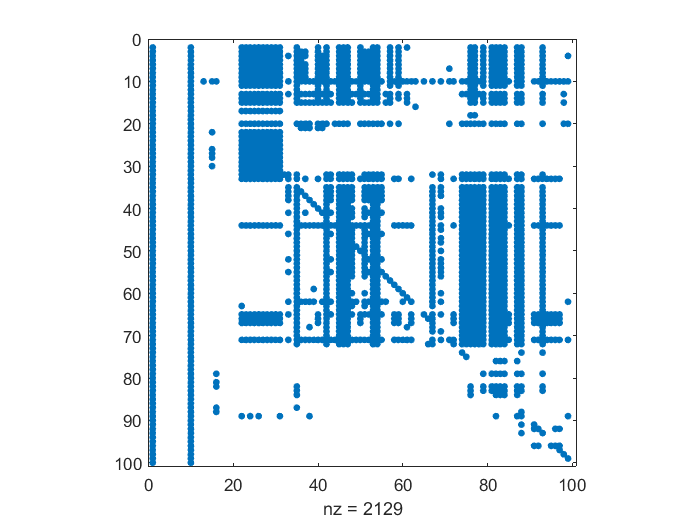

spy(G);

A partire dalla matrice `G`, si ricava il grafo associato ad essa. I numeri stampati sono gli identificativi delle pagine: a ciascuno di essi è associato un URL.

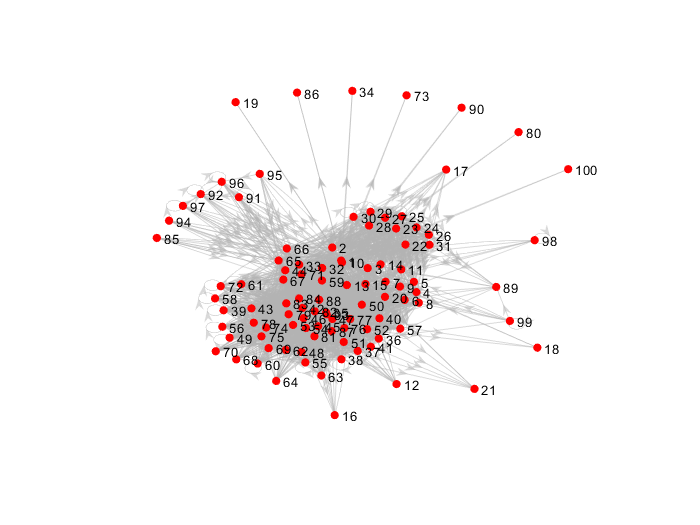

ff = digraph(G');
plot(ff,'NodeColor','r','EdgeColor', [.7 .7 .7]); 
axis off

## Utilizzo dell'algoritmo `PageRank `

L'algoritmo `PageRank` restituisce il vettore dei rank delle pagine: se l'elemento di indice 22 ha rank 0.0567, vuol dire che la pagina con l'identificativo 22 ha quel rank. Inoltre, vengono restituiti i vettori contenenti gli indegree e outdegree di ciascuna pagina. Successivamente alla generazione del vettore dei rank, sono state aggiornate le proprietà del grafo.

[R, OUTDEGREE, INDEGREE] = PageRank(G);
% Assegno le proprietà al grafo
ff.Nodes.PageRank = R;
ff.Nodes.InDegree = INDEGREE;
ff.Nodes.OutDegree = OUTDEGREE;

Di seguito sono stampati i primi 15 risultati in ordine decrescente, con i corrispondenti outdegree e indegree:

[R, index] = sort(R,'descend');
sites = U(index(1:15));
ID = index(1:15);
rank = R(1:15);
outdegree = OUTDEGREE(index(1:15));
indegree = INDEGREE(index(1:15));
T = table(ID,rank,outdegree,indegree,'RowNames',sites)

T = 15×4 table
                                                                          ID      rank      outdegree    indegree
                                                                          __    ________    _________    ________

    http://www.repubblica.it                                              10    0.093172    98           70      
    http://d.repubblica.it                                                71    0.038227     3           63      
    http://www.repubblica.it/adagiojs/adagiorep.js                        20    0.033803     0           47      
    http://design.repubblica.it                                           44    0.027891     3           59      
    http://video.repubblica.it/home                                       72   

Disegno l'istogramma che rappresenta il pagerank di ogni URL in U e rappresento su un grafo tutti i nodi (URL) che hanno un pagerank superiore alla media:

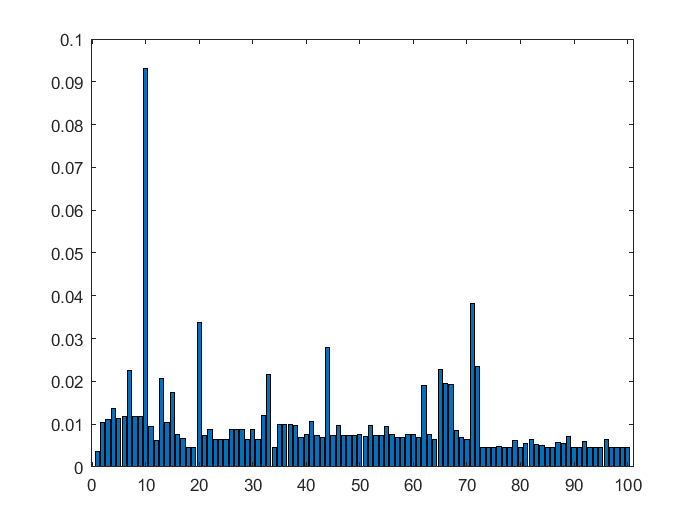

bar(ff.Nodes.PageRank); 

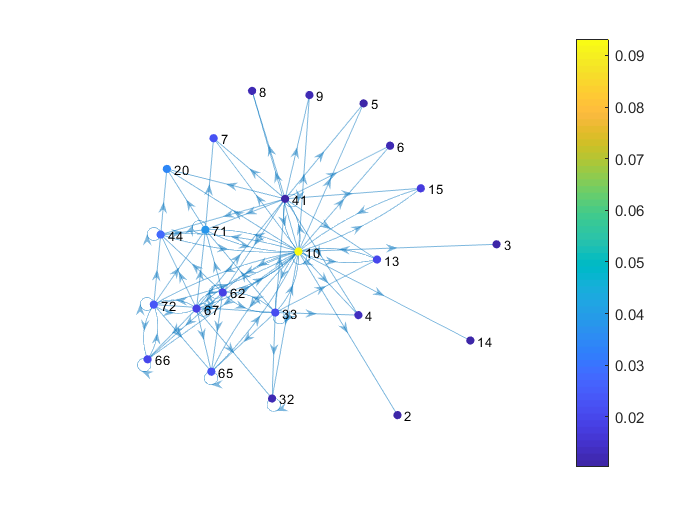

H = subgraph(ff, find(ff.Nodes.PageRank > mean(ff.Nodes.PageRank)));
plot(H,'NodeLabel',find(ff.Nodes.PageRank > mean(ff.Nodes.PageRank)),'NodeCData',H.Nodes.PageRank,'Layout','force'); colorbar; axis off;

# Test di correttezza

Per valutare la correttezza dell'algoritmo implementato è stato preso come riferimento il risultato restituito dalla funzione `centrality` del Matlab: la tabella ottenuta riporta le stesse informazioni di quella calcolata in precedenza.

ff = digraph(G','OmitSelfLoops');
pr = centrality(ff,'pagerank','FollowProbability',0.85,'Tolerance',1e-7);
c = ff.outdegree; r = ff.indegree; 
[pr, index] = sort(pr,'descend');
outdegrees = c(index(1:15));
indegrees = r(index(1:15));
sites = U(index(1:15));
T = table(ID,pr(1:15),outdegrees,indegrees,'RowNames',sites,'VariableNames',{'ID','rank','outdegree','indegree'})

T = 15×4 table
                                                                          ID      rank      outdegree    indegree
                                                                          __    ________    _________    ________

    http://www.repubblica.it                                              10    0.093172    98           70      
    http://d.repubblica.it                                                71    0.038227     3           63      
    http://www.repubblica.it/adagiojs/adagiorep.js                        20    0.033803     0           47      
    http://design.repubblica.it                                           44    0.027891     3           59      
    http://video.repubblica.it/home                                       72   

# Test di robustezza

I test sono stati progettati in modo che tutte le condizioni di errore/warning fossero attivate almeno una volta. Nell'implementazione è stato usato il framework di Matlab per il testing di unità; questa scelta ha permesso di automatizzare completamente l'esecuzione dei test: infatti, è possibile lanciare la simulazione con l'istruzione:

results = runtests('test_suite.m')

Running test_suite
....

.
Done test_suite
__________



results =   1×5 TestResult array with properties:

    Name
    Passed
    Failed
    Incomplete
    Duration
    Details

Totals:
   5 Passed, 0 Failed, 0 Incomplete.
   0.081941 seconds testing time.


Per completezza è stato progettato anche un caso di test apposito che verificasse il funzionamento dell'algoritmo in presenza di self loop: essi infatti indicano link di pagine web che si autoreferenziano e che quindi non devono essere considerati nel calcolo del rank; si riporta di seguito la function implementata:

function testFunctionCase5(testCase)
% Configurazione parametri bisection_algorithm
%   - G -> valido
% Verifico che i self loop non influenzano l'esecuzione dell'algoritmo
    
    G_loop = round(sprand(10,10,0.2)*10) + spdiags(ones(10,1),0,10,10);
    G = G_loop - spdiags(G_loop,0,10,10);

    R_loop = PageRank(G_loop);
    R = PageRank(G);
    
    if abs(R_loop-R)<eps
        % passed
        verifyReturnsTrue(testCase,@true);
    else
        % not passed
        verifyReturnsTrue(testCase,@false);
    end
end


Come ci si aspetta, le due esecuzioni dell'algoritmo su `G `(grafo con i self loop) e  `G_loop `(grafo senza loop) restituiscono lo stesso risultato.

## Autori                                                                                                                          

Valerio La Gatta, Marco Postiglione